# Example Distributed Monitoring 

 Given a submodular clustering problem solved by sequential greedy in a probabilistic message passing environment. Which agents are more likely to be reinforced in order to increase the performance?

We are going to define an environment where A agents should greedily coordinate their decisions in a communication sequence in order to find the most global optimal deployment. Firstly, let us **define the environment ** with characteristics:

warning('off','all');clear all;close all;clc; 
addpath('plot'); addpath('auxiliar');
% Dimensions
N = 1000;  % Number of points                     
m = 25;    % Number of possible placements         
p = 8;     % Number of agents                      
s = 16;    % Size of the partition for each agent   
k = 2;     % Number of picks for each agent 

Let us create an environment,                      

points  = generateRandomPoints(N);
centers = chooseRandomPoints(points, m);
indices = randperm(length(centers));
centers = centers(indices,:);
[agents,radii,randomDom] = generateRandomRadii(p,m,s);
normal_points = generateNormalRandomPoints(centers);

Plot the environment, with *save* variable the dataset can be saved for future use. Here is set to *0*. 

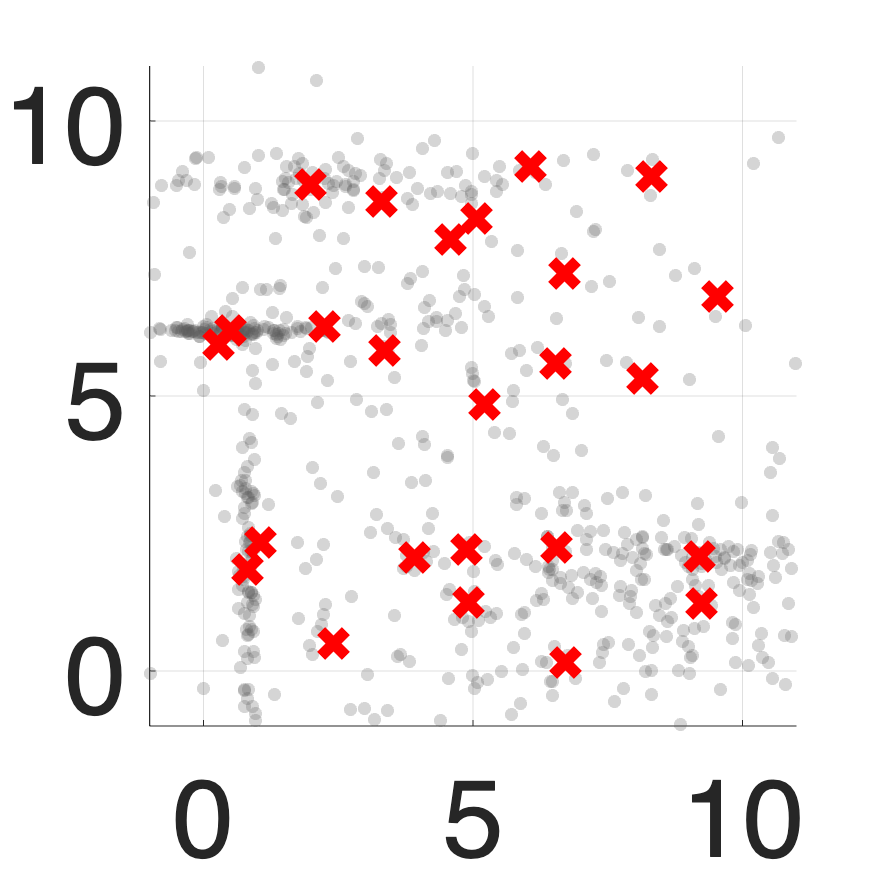

plotPoints(normal_points, centers, 0);

Second, let us run an experiment to show Resource Allocation importance:

1 - Run SeqGreedy considering perfect communication

2 - Run SeqGreedy considering probabilistic communication

3 - Run SeqGreedy considering the reinforcement of each possible agent independently

First, let us settle down some communication properties

sequence = 1:p; 
p_success = 0.7 + (1-0.7) * rand(1,p);
epochs = 100;

Let us proceed with the example. First,

[realSelectedCenters_perfect,f_val_perfect] = run_k_simulations(ones(1,p),sequence,ones(1,p), ...
                                                                epochs,normal_points,centers, ...
                                                                randomDom,radii,k,s);
[~,alpha_1] = probabilistic_force(ones(1,p));
% plot the results
fprintf("Assuming perfect communication:\n")

Assuming perfect communication:


fprintf("   -> f_val = %.2f\n", sum(f_val_perfect)/epochs)

   -> f_val = 279.00


fprintf("   -> alpha = %.2f\n", alpha_1)

   -> alpha = 0.50


Second,

[realSelectedCenters_base,f_val_base] = run_k_simulations(p_success,sequence,ones(1,p), ...
                                                          epochs,normal_points,centers, ...
                                                          randomDom,radii,k,s);
[~,alpha_2] = probabilistic_force(p_success);
% plot the results
fprintf("Assuming probabilistic communication:\n")

Assuming probabilistic communication:


fprintf("   -> f_val = %.2f\n", sum(f_val_base)/epochs)

   -> f_val = 258.77


fprintf("   -> alpha = %.2f\n", alpha_2)

   -> alpha = 0.30


Third,

results = rand(2, p); % save f_val and alpha for the reinforcement of each agent
SelectedCenters = zeros(s,numel(agents)-1);
for idx = 1:p
    n_trials = ones(1,p); n_trials(idx) = n_trials(idx)+1;
    [realSelectedCenters,f_val] = run_k_simulations(p_success,sequence,n_trials, ...
                                                    epochs,normal_points,centers, ...
                                                    randomDom,radii,k,s);
    alpha = optimality_gap(p_success,n_trials);
    % save the values
    results(1,idx) = sum(f_val)/epochs;
    results(2,idx) = alpha;
    SelectedCenters(:,idx) = realSelectedCenters;
end
% plot the results
variable_names = arrayfun(@(x) sprintf('Agent_%d', x), 1:p, 'UniformOutput', false);
result_table = array2table(results, 'VariableNames', variable_names);
disp(result_table);

    Agent_1    Agent_2    Agent_3    Agent_4    Agent_5    Agent_6    Agent_7    Agent_8
    _______    _______    _______    _______    _______    _______    _______    _______

      261.6      253.9     264.12     261.26     262.12     263.15      260.7    261.58 
    0.32128    0.30344    0.31379    0.31816    0.31236    0.33341    0.31174    0.3196 



Let us plot the placement for the best agent,

[~,best_agent] = max(results(2,:));
fprintf("The best agent to get extra resources is agent %.2f",best_agent)

The best agent to get extra resources is agent 6.00

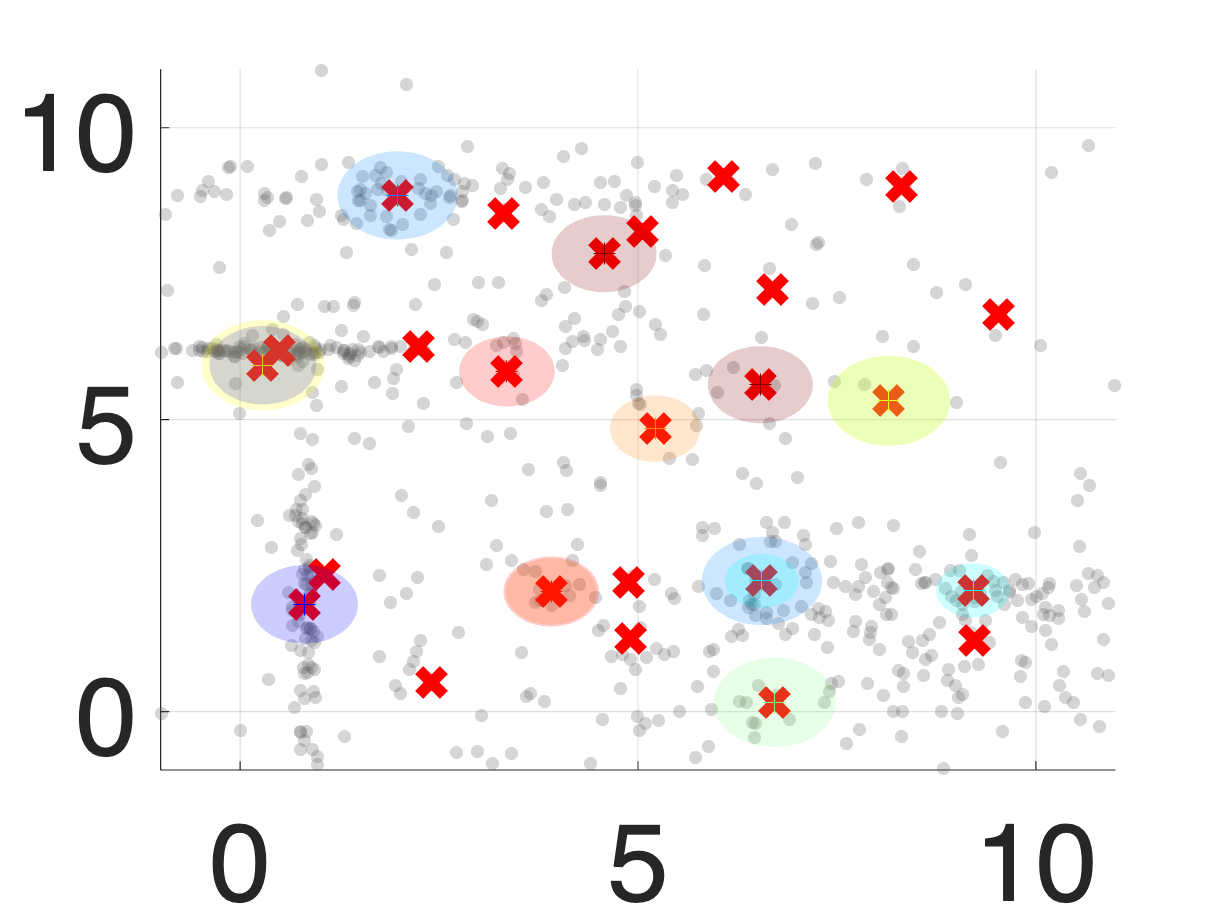

plot_points_with_circles(normal_points,centers,SelectedCenters(:,best_agent), ...
                                                           radii,2, 'example.svg',0);